### Plots & Diagrams

clear;
neatov2.connect()

Deleting previous Neato connection.
Connecting to the Neato.


ans =   neatov2 with no properties.


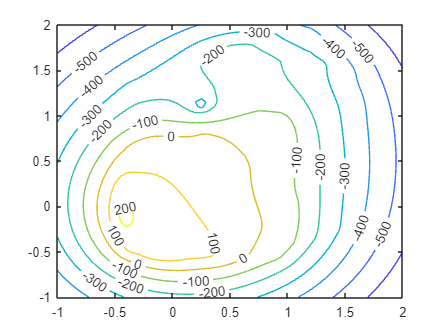


[x,y]=meshgrid(-1:0.05:2,-1:0.05:2); % define the potential at all mesh points

v = 100*log(sqrt((x-0.244).^2+(y-1.128).^2)); % function that defines Bob as sink

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    v = build_equation(v, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

% plot contours with levels marked
figure();
contour(x,y,v,'ShowText','On')


neatov2.setFlatlandContours(x,y,v);

% plot surface
% figure();
% surf(x, y, v)

### Gradient Set-up

syms x y

% flatlands
f = 100*log(sqrt((x-0.244).^2+(y-1.128).^2));

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    f = build_equation(f, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

fx = diff(f,x);
fy = diff(f,y);
gradient = [fx, fy];

### Implementation: Run Neato

newOrientation = 0.7854

distance = 23.1371

r_list =          0   13.8084
         0    8.7744


newOrientation = 0.7854

distance = 1.4508

r_list =          0   13.8084   14.5358
         0    8.7744    9.4978


newOrientation = 0.7854

distance = 1.3056

r_list =          0   13.8084   14.5358   15.1903
         0    8.7744    9.4978   10.1489


newOrientation = 0.7854

distance = 1.1929

r_list =          0   13.8084   14.5358   15.1903   15.7882
         0    8.7744    9.4978   10.1489   10.7439


newOrientation = 0.7854

distance = 1.1022

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405
         0    8.7744    9.4978   10.1489   10.7439   11.2938


newOrientation = 0.7854

distance = 1.0273

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063


newOrientation = 0.7854

distance = 0.9642

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874


newOrientation = 0.7854

distance = 0.9101

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415


newOrientation = 0.7854

distance = 0.8631

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722


newOrientation = 0.7854

distance = 0.8218

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823


newOrientation = 0.7854

distance = 0.7852

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742


newOrientation = 0.7854

distance = 0.7525

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498


newOrientation = 0.7854

distance = 0.7230

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087   19.7709
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498   14.7107


newOrientation = 0.7854

distance = 0.6963

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087   19.7709   20.1196
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498   14.7107   15.0582


newOrientation = 0.7854

distance = 0.6719

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087   19.7709   20.1196   20.4561
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498   14.7107   15.0582   15.3936


newOrientation = 0.7854

distance = 0.6496

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087   19.7709   20.1196   20.4561   20.7815
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498   14.7107   15.0582   15.3936   15.7179


newOrientation = 0.7854

distance = 0.6291

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087   19.7709   20.1196   20.4561   20.7815   21.0965
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498   14.7107   15.0582   15.3936   15.7179   16.0319


newOrientation = 0.7854

distance = 0.6101

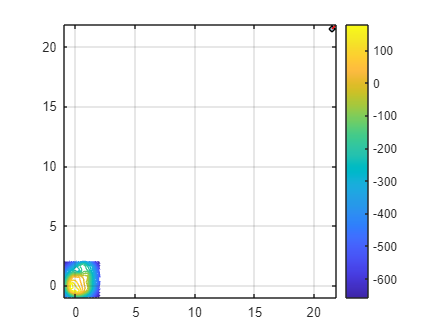

r_list =          0   13.8084   14.5358   15.1903   15.7882   16.3405   16.8553   17.3384   17.7944   18.2268   18.6385   19.0318   19.4087   19.7709   20.1196   20.4561   20.7815   21.0965   21.4021
         0    8.7744    9.4978   10.1489   10.7439   11.2938   11.8063   12.2874   12.7415   13.1722   13.5823   13.9742   14.3498   14.7107   15.0582   15.3936   15.7179   16.0319   16.3365


%Starting position and orientation
startingx = 0;
startingy = 0;
startingTheta = 0;

%Parameters
lambda = 1;
linearWheelV = 0.3;

%While loop parameters
i = 2;
i_max = 20;

%Initial position and gradient
r_0 = [startingx; startingy]; %First coordinate
r_list(:,1) = r_0;
r = r_0;

grad = double(subs(gradient, {x, y}, {r(1), r(2)}));
neatov2.setPositionAndOrientation(startingx,startingy,startingTheta)

%%FOR NON-SIMULATED%%
%orientation = startingTheta

while i < i_max && norm(grad) > 0.5
    grad = double(subs(gradient, {x, y}, {r(1), r(2)}));
    % CHANGE FOR #6: make lambda proportional to the gradiant
    lambda = 0.09*norm(grad); % default lambda
    if norm(grad) > 4 % adjust lambda for extra steep steps
        lambda = 0.0005*norm(grad);
    end
    next_r = r - lambda*grad;
    vectorDiff = next_r-r;
    newOrientation = atan2(vectorDiff(2),vectorDiff(1))

    %%FOR NON-SIMULATED%%
    %deltaTheta = newOrientation-orientation;
    %angularV = -0.1/0.254;
    %spinTime = abs(deltaTheta/angularV);
    %neatov2.driveFor(spinTime, sign(deltaTheta)*-0.05, sign(deltaTheta)*0.05, true);
    %pause(.01)

    distance = norm(vectorDiff)
    % CHANGE FOR #6: if distance of path is insignificant, end the loop
    if distance < 0.0018
        break
    end
    driveTime = distance/linearWheelV;
    neatov2.setPositionAndOrientation(r(1),r(2),newOrientation)
    neatov2.driveFor(driveTime, linearWheelV, linearWheelV, true)

    %%FOR NON-SIMULATED%%
    %pause(.01)

    r = next_r;
    r_list(:,i) = r(1,:);
    i = i + 1;

    %%FOR NON-SIMULATED%%
    %orientation = newOrientation; 
end

### Helper Functions

function [v] = build_equation(v, x, y, x_coord, y_coord)
% Add new source to equation evaluted at meshgrid.
%
% Inputs
%   v (square matrix): Equation evaluted at meshgrid
%   x (square matrix): X coordinates of meshgrid
%   y (square matric): Y coordinates of meshgrid
%   x_coord (float): X coordinate of source
%   y_coord(float): Y coordinate of source
%
% Returns
%   v (square matrix): Newly built equation evaluted at meshgrid

    v = v - (log(sqrt((x-x_coord).^2+(y-y_coord).^2)));
end